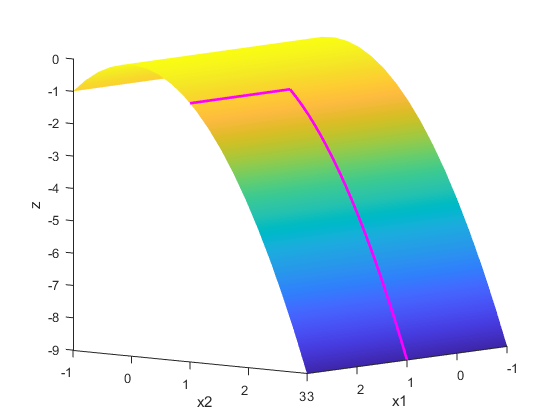

clear
clc
close all

%First graph:
x1 = linspace(-1, 3, 20);
x2 = linspace(-1, 3, 20);
[X1, X2] = meshgrid(x1, x2);
Z = -X2.^2;

figure
xlabel('x1')
ylabel('x2')
zlabel('z')
hold on
surf(X1, X2, Z);
view([-229.5000, 7.2000]);
shading interp

x1_line = ones(1, 20);
x2_line = linspace(1, 3, 20);

%Approach from x1
z_line = -x1_line.^2;
plot3(x2_line, x1_line, z_line, 'm', 'LineWidth', 2);

%Approach from x2
z_line = -x2_line.^2;
plot3(x1_line, x2_line, z_line, 'm', 'LineWidth', 2);


%Second graph:
x1 = linspace(-20, 20, 20);
x2 = linspace(-20, 20, 20);
[X1, X2] = meshgrid(x1, x2);
Z2 = -X1.^2-X2.^2;
figure
hold on
grid on
shading interp
meshc(X1, X2, Z2);
view([-229.5000, 7.2000]);
xlabel('x1')
ylabel('x2')
zlabel('z')

syms x1 x2
j = jacobian([-x1^2-x2^2], [x1, x2])

$$j = \left(\begin{array}{cc} -2\,x_{1} & -2\,x_{2} \end{array}\right)$$

approx_at = [-13.6 -11.5]

approx_at =   -13.6000  -11.5000


eval_at = -(approx_at(1)^2)-(approx_at(2)^2)

eval_at = -317.2100

%Evaluate jacobian at approx_at
slope_at = subs(j, [x1 x2], approx_at)

$$slope\_at = \left(\begin{array}{cc} \frac{136}{5} & 23 \end{array}\right)$$


%Draw tangent plane
Z3 = (slope_at(1)*(X1-approx_at(1)))+(slope_at(2)*(X2-approx_at(2)))+eval_at;
%mesh(X1, X2, double(Z3));

scatter3(approx_at(1), approx_at(2), eval_at, 200)

%% For every differentiable function f : Rn -> R and every point x in Rn,
%% the gradient ∇f(x) points in the direction of steepest ascent of f at x.
v1 = [approx_at(1) approx_at(2) eval_at]

v1 =   -13.6000  -11.5000 -317.2100


v2 = [slope_at(1) slope_at(2) eval_at]

$$v2 = \left(\begin{array}{ccc} \frac{136}{5} & 23 & -\frac{31721}{100} \end{array}\right)$$

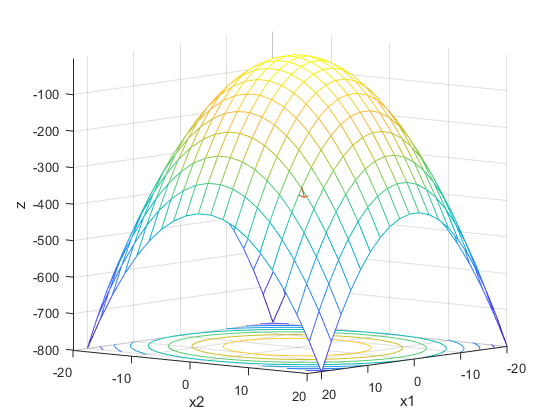

dp = v2-v1; 
quiver3(v1(1),v1(2),v1(3),dp(1),dp(2),dp(3))